# Plate recognition test, Matlab, Sensor course, Image processing lab N.4

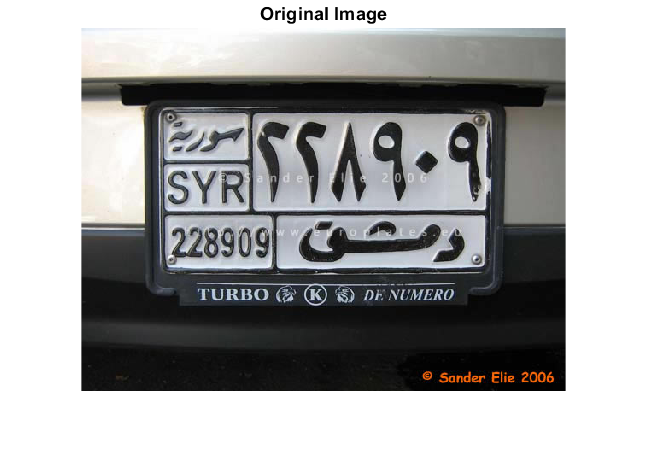


close all;
clear all;


% Read the image from path directory
%im = imread('Plate Image/image1.jpg');
%origial = imread('Plate Image/image1.jpg');

% or 
% Prompt the user to enter the URL of the image to read
url = input('Enter the URL of the image to read: ', 's'); %% Enter image address from the internet
% Links : https://licenseplatemania.com/fotos/tsjechie/tsjechie52.jpg
%         https://www.europlates.eu/images/plates/cz/P00097.JPG
%         https://www.europlates.eu/images/plates/syr/P00263.JPG

% Read the image from the URL
origial = imread(url);
im = imread(url);

% Display the original image
figure; imshow(im); title('Original Image');

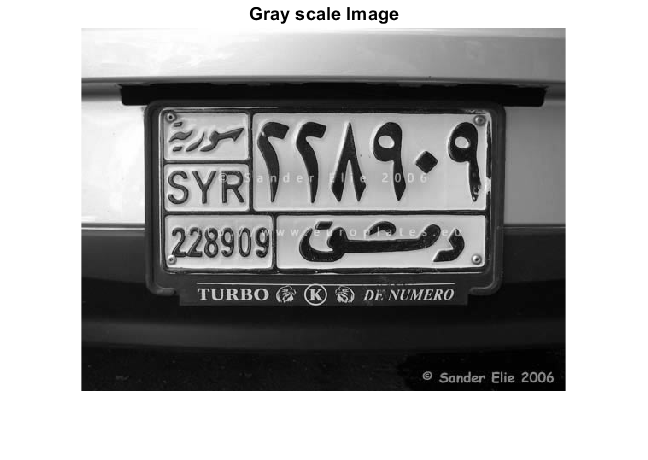


imgray = rgb2gray(im);% Convert the image to grayscale
imbin = imbinarize(imgray);% Threshold the image to binary
im = edge(imgray, 'prewitt'); % Perform edge detection

% Display the grayscale image
figure; imshow(imgray); title('Gray scale Image');

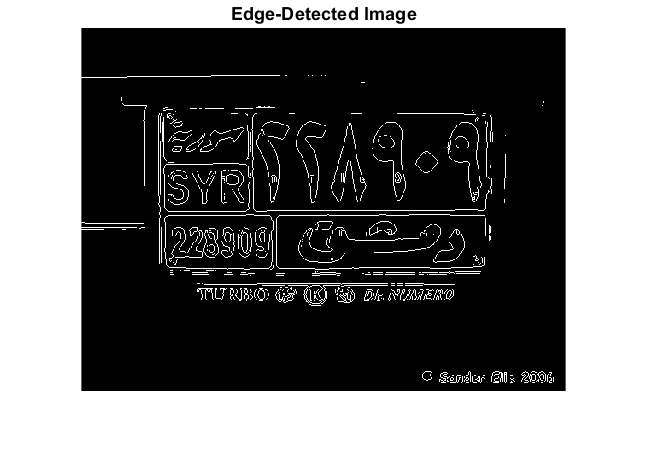


% Display the edge-detected image
figure; imshow(im); title('Edge-Detected Image');

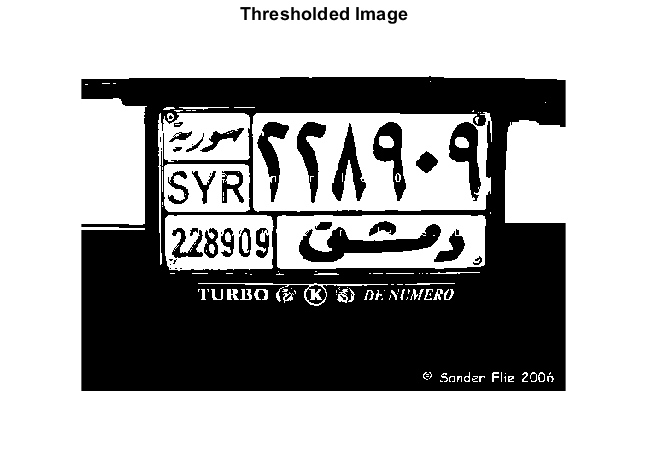


% Display the thresholded image
figure; imshow(imbin); title('Thresholded Image');

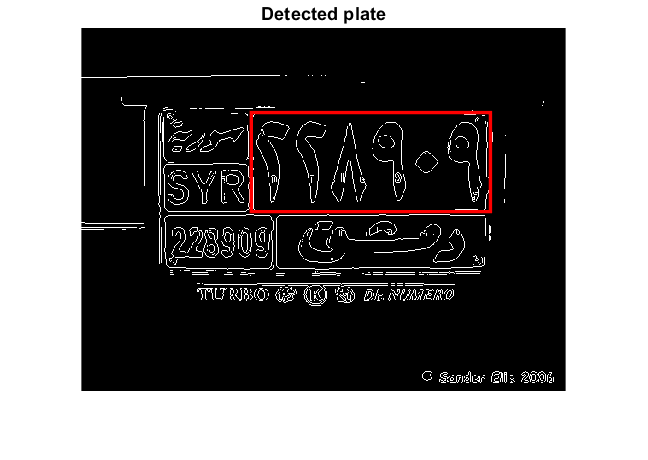


% Find the location of the number plate
Iprops=regionprops(im,'BoundingBox','Area', 'Image');
area = Iprops.Area;
count = numel(Iprops);
maxa= area;
boundingBox = Iprops.BoundingBox;
for i=1:count
   if maxa<Iprops(i).Area
       maxa=Iprops(i).Area;
       boundingBox=Iprops(i).BoundingBox;
   end
end    

% Draw a rectangle around the bounding box of the detected number plate
figure;
imshow(im);imshow(im); title('Detected plate');
hold on;
rectangle('Position', boundingBox, 'EdgeColor', 'r', 'LineWidth', 2);

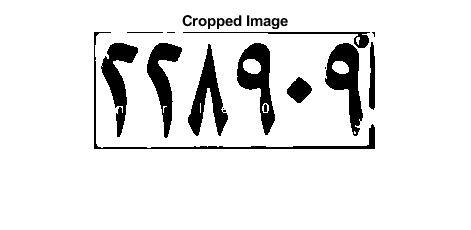



%Crop the number plate area
im = imcrop(imbin, boundingBox);
% Display the cropped number plate area
figure; imshow(im); title('Cropped Image');

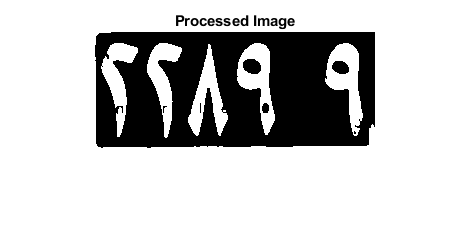



% Remove some objects if their width is too long or too small than 500
im = bwareaopen(~im, 500); 
% Display the processed image
figure; imshow(im); title('Processed Image');



[h, w] = size(im);%get width

Iprops=regionprops(im,'BoundingBox','Area', 'Image'); %read letters
count = numel(Iprops);
noPlate=[]; % Initializing the variable of number plate string.



for i=1:count
   ow = length(Iprops(i).Image(1,:));
   oh = length(Iprops(i).Image(:,1));
   if ow<(h/2) & oh>(h/3)
       letter=Letter_detection(Iprops(i).Image); % Reading the letter corresponding the binary image 'N'.
       noPlate=[noPlate letter] % Appending every subsequent character in noPlate variable.
   end
end

ind = 27

noPlate = 'T'

ind = 27

noPlate = 'TT'

ind = 2

noPlate = 'TTA'

ind = 26

noPlate = 'TTAS'

ind = 26

noPlate = 'TTASS'



% Display the detected number plate
disp(['Detected Number Plate: ', noPlate]);

Detected Number Plate: TTASS



% Display the original image
figure; imshow(origial); title('Original Image');